clc;
clear;
close all;

msym_tb=readcsv("1_MMFFSYMB.csv");
bs_tb=readcsv("6_MMFFBOND.csv");
ab_tb=readcsv("8_MMFFANG.csv");
sb_tb=readcsv("9_MMFFSTBN.csv");
opb_tb=readcsv("11_MMFFOOP.csv");

opb_tb = 117×6 table
    MTYPE_I    MTYPE_J    MTYPE_K    MTYPE_L    KOOP           SOURCE       
    _______    _______    _______    _______    _____    ___________________

       0          2          0          0        0.02    {'*-2-*-* C94 DEF'}
       1          2          1          2        0.03    {'C94'            }
       1          2          2          2       0.027    {'C94'            }
       1          2          2          3       0.026    {'C94'            }
       1          2          2          5       0.013    {'C94'            }
       1          2          2         37       0.032    {'C94'            }
       2          2          2          5       0.013    {'C94'            }
       2          2          3          5       0.012    {'C94'            }
       2          2          5          5       0.006    {'C94'            }
       2          2          5          6       0.027    {'C94'            }
       2          2          5         37       0.017 

ti_tb=readcsv("12_MMFFTOR.csv");

ti_tb = 926×9 table
    TT    MTYPE_I    MTYPE_J    MTYPE_K    MTYPE_L      V1        V2       V3             SOURCE        
    __    _______    _______    _______    _______    ______    ______    _____    _____________________

    0        0          1          1          0            0         0      0.3    {'C94 0:*-1-1-* Def'}
    5        0          1          1          0          0.2      -0.8      1.5    {'C94 5:*-1-1-* Def'}
    0        1          1          1          1        0.103     0.681    0.332    {'C94'              }
    5        1          1          1          1        0.144    -0.547    1.126    {'C94'              }
    0        1          1          1          2       -0.295     0.438    0.584    {'C94'              }
    0        1          1          1          3        0.066    -0.156    0.143    {'C94'              }
    0        1          1          1          5        0.639     -0.63    0.264    {'C94'              }
    0        1          1         

vdw_tb=readcsv("13_MMFFVDW.csv");

vdw_tb = 95×8 table
    MTYPE    ALPHA_I    N_I     A_I      G_I      DA       SYMBOL     ORIGIN 
    _____    _______    ____    ____    _____    _____    ________    _______

      1       1.05      2.49    3.89    1.282    {'-'}    {'CR'  }    {'E94'}
      2       1.35      2.49    3.89    1.282    {'-'}    {'C=C' }    {'E94'}
      3        1.1      2.49    3.89    1.282    {'-'}    {'C=O' }    {'E94'}
      4        1.3      2.49    3.89    1.282    {'-'}    {'CSP' }    {'E94'}
      5       0.25       0.8     4.2    1.209    {'-'}    {'HC'  }    {'C94'}
      6        0.7      3.15    3.89    1.282    {'A'}    {'OR'  }    {'C94'}
      7       0.65      3.15    3.89    1.282    {'A'}    {'O=C' }    {'C94'}
      8       1.15      2.82    3.89    1.282    {'A'}    {'NR'  }    {'C94'}
      9        0.9      2.82    3.89    1.282    {'A'}    {'N=C' }    {'C94'}
     10          1      2.82    3.89    1.282    {'A'}    {'NC=O'}    {'E94'}
     11       0.35      3.48    3.89    1.2

%% 需要一般化的部分
ori_str="CCC";
nhc=3;
hc=2*nhc+2;
ac=nhc+hc;

%通过一个函数完成H的引入
nh_tb=readtable("CCC_TEST/CCC_NH.csv")

nh_tb = 3×9 table
    Seq    Element    MType    IsAroma    CCount    CHCount    NHBC    CharSym    CharVal
    ___    _______    _____    _______    ______    _______    ____    _______    _______

     0      {'C'}       1         0         1          3        1         0          0   
     1      {'C'}       1         0         2          2        2         0          0   
     2      {'C'}       1         0         1          3        1         0          0   


h_tb=readtable("CCC_TEST/CCC_H.csv")

h_tb = 8×3 table
    Seq    ParentSeq    MType
    ___    _________    _____

     3         0          5  
     4         0          5  
     5         0          5  
     6         1          5  
     7         1          5  
     8         2          5  
     9         2          5  
    10         2          5  


mtype_all_arr=[nh_tb{:,"MType"};h_tb{:,"MType"}]

mtype_all_arr =      1
     1
     1
     5
     5
     5
     5
     5
     5
     5




%邻接表
keys={'0','1','2'};
values={[1,3,4,5],[0,2,6,7],[1,8,9,10]};
adj_list=dictionary(keys,values);

%扩展邻接表
big_key=string(0:(ac-1))

big_key = 1×11 string 数组
    "0"    "1"    "2"    "3"    "4"    "5"    "6"    "7"    "8"    "9"    "10"


big_values={[1,3,4,5],[0,2,6,7],[1,8,9,10],0,0,0,1,1,2,2,2}

big_values = 1×11 cell 数组
    {[1 3 4 5]}    {[0 2 6 7]}    {[1 8 9 10]}    {[0]}    {[0]}    {[0]}    {[1]}    {[1]}    {[2]}    {[2]}    {[2]}


big_adj_list=dictionary(big_key,big_values);

%% 数据表格预处理
nhc_all_tb=nh_tb{:,"NHBC"}+nh_tb{:,"CHCount"};

bs_pro_arr=gen12Darr(bs_tb,["MTYPE_I" "MTYPE_J"],["KB","R0"])

bs_pro_arr = bs_pro_arr(:,:,1) =

    4.2580    4.5390    4.1900    4.7070    4.7660    5.0470       NaN    5.0840    4.7630    4.6640    6.0110    2.9740    2.5290    1.7060    2.8930       NaN    2.8410    3.2580    2.8660    4.6500       NaN    4.2860       NaN       NaN    2.9800    2.7900       NaN       NaN       NaN       NaN       NaN       NaN       NaN    3.8440    7.9150       NaN    4.9570       NaN    6.1140    4.9220    3.8300       NaN    3.9710       NaN    3.8440    3.8130       NaN       NaN       NaN       NaN       NaN       NaN       NaN    4.2670    4.6460    4.1660    4.6690    4.3290       NaN       NaN    4.8450    4.4560    4.4810    4.5180       NaN       NaN    4.1880    4.2170       NaN       NaN       NaN    2.9560    2.6080       NaN    2.5470       NaN       NaN    4.5930       NaN    4.3730    4.5120       NaN
    4.5390    5.3100    4.5650    5.6570    5.1700    5.5200       NaN       NaN    6.3850    6.3290    6.2830    3.3900    3.4130    2.0620    3

[ab_fast_arr,ab_cmpl_arr]=gen34Darr(ab_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K"],["KA_IJK","THETA_0"])

arr =          0    1.0000         0         0  108.9000
    1.0000    1.0000    1.0000    0.8510  109.6080
    1.0000    1.0000    2.0000    0.7360  109.4450
    1.0000    1.0000    3.0000    0.7770  107.5170
    1.0000    1.0000    4.0000    1.0060  110.2650
    1.0000    1.0000    5.0000    0.6360  110.5490
    1.0000    1.0000    6.0000    0.9920  108.1330
    1.0000    1.0000    8.0000    0.7770  108.2900
    1.0000    1.0000    9.0000    1.1360  108.1940
    1.0000    1.0000   10.0000    1.0500  109.9600


issize =     62    57    79


short_arr =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    28    29    30    31    32    34    35    36    37    38    39    40    41    42    43    44    45    46    50    53    55    56    57    58
     1     2     3     4     6     8     9    10    15    17    18    19    20    22    25    26    30    34    37    38    39    40    41    43    44    45    46    48    49    51    53    54    55    56    57    58    59    61    62    63    64    65    66    67    68    69    70    73    74    75
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    50    51


cmpl_arr =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26     0    27    28    29    30    31     0    32    33    34    35    36    37    38    39    40    41    42    43    44     0     0     0    45
     1     2     3     4     0     5     0     6     7     8     0     0     0     0     9     0    10    11    12    13     0    14     0     0    15    16     0     0     0    17     0     0     0    18     0     0    19    20    21    22    23     0    24    25    26    27     0    28    29     0
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48     0    49


ab_fast_arr = ab_fast_arr(:,:,1,1) =

    0.8510    0.7520    1.1510       NaN    1.1970    1.0900       NaN    1.1170    1.6540    1.4150    1.2300    0.6160    0.9430    0.9030    1.0720    1.0850       NaN    0.8620       NaN       NaN       NaN    1.0640       NaN    1.1090       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.9230    0.9510       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    1.1590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.7360    0.6840    1.1060       NaN    0.9670       NaN       NaN    1.0040    1.3210    1.3870    1.2640       NaN       NaN    0.8840       NaN       NaN       NaN    1.1540       NaN       NaN       NaN    0.9980       NaN    1.0520       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

ab_cmpl_arr =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26     0    27    28    29    30    31     0    32    33    34    35    36    37    38    39    40    41    42    43    44     0     0     0    45
     1     2     3     4     0     5     0     6     7     8     0     0     0     0     9     0    10    11    12    13     0    14     0     0    15    16     0     0     0    17     0     0     0    18     0     0    19    20    21    22    23     0    24    25    26    27     0    28    29     0
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48     0    49


[sb_fast_arr,sb_cmpl_arr]=gen34Darr(sb_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K"],["KBA_IJK","KBA_KJI"])

arr =     1.0000    1.0000    1.0000    0.2060    0.2060
    1.0000    1.0000    2.0000    0.1360    0.1970
    1.0000    1.0000    3.0000    0.2110    0.0920
    1.0000    1.0000    5.0000    0.2270    0.0700
    1.0000    1.0000    6.0000    0.1730    0.4170
    1.0000    1.0000    8.0000    0.1360    0.2820
    1.0000    1.0000   10.0000    0.1870    0.3380
    1.0000    1.0000   11.0000    0.2090    0.6330
    1.0000    1.0000   12.0000    0.1760    0.3860
    1.0000    1.0000   15.0000    0.1390    0.2170


issize =     38    37    51


short_arr =      1     2     3     5     6     7     8     9    10    11    12    15    18    20    22    23    28    29    31    32    36    37    38    39    40    43    44    50    55    56    58    59    63    64    65    71    78    81     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     3     6     8     9    10    15    18    20    22    26    30    34    37    38    39    40    41    43    44    49    54    55    56    57    59    63    64    65    66    68    69    70    78    80    81     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     3     5     6     7     8     9    10    11    12    15    18    20    21    22    23    24    27    28    29    30    31    32    33    34    36    37    38    39    40    41    43    44    50    54    55    56    57    58    59    63    64    65    66    68    69    71    78    80


cmpl_arr =      1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14     0    15    16     0     0     0     0    17    18     0    19    20     0     0     0    21    22    23    24    25     0     0    26    27     0     0     0     0     0    28
     1     2     3     0     0     4     0     5     6     7     0     0     0     0     8     0     0     9     0    10     0    11     0     0     0    12     0     0     0    13     0     0     0    14     0     0    15    16    17    18    19     0    20    21     0     0     0     0    22     0
     1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14    15    16    17    18     0     0    19    20    21    22    23    24    25    26     0    27    28    29    30    31    32     0    33    34     0     0     0     0     0    35


sb_fast_arr = sb_fast_arr(:,:,1,1) =

    0.2060    0.2500    0.3580    0.3090    0.3120       NaN    0.0630    0.1250    0.0230       NaN       NaN       NaN       NaN    0.2020       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.2170       NaN       NaN       NaN       NaN       NaN
    0.1360    0.2220    0.2460    0.1570       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2110    0.2440    0.3030   -0.1530       NaN    0.3260   -0.0210       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

sb_cmpl_arr =      1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14     0    15    16     0     0     0     0    17    18     0    19    20     0     0     0    21    22    23    24    25     0     0    26    27     0     0     0     0     0    28
     1     2     3     0     0     4     0     5     6     7     0     0     0     0     8     0     0     9     0    10     0    11     0     0     0    12     0     0     0    13     0     0     0    14     0     0    15    16    17    18    19     0    20    21     0     0     0     0    22     0
     1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14    15    16    17    18     0     0    19    20    21    22    23    24    25    26     0    27    28    29    30    31    32     0    33    34     0     0     0     0     0    35


[opb_fast_arr,opb_cmpl_arr]=gen34Darr(opb_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K" "MTYPE_L"],"KOOP","Yes")

arr =          0    2.0000         0         0    0.0200
    1.0000    2.0000    1.0000    2.0000    0.0300
    1.0000    2.0000    2.0000    2.0000    0.0270
    1.0000    2.0000    2.0000    3.0000    0.0260
    1.0000    2.0000    2.0000    5.0000    0.0130
    1.0000    2.0000    2.0000   37.0000    0.0320
    2.0000    2.0000    2.0000    5.0000    0.0130
    2.0000    2.0000    3.0000    5.0000    0.0120
    2.0000    2.0000    5.0000    5.0000    0.0060
    2.0000    2.0000    5.0000    6.0000    0.0270


issize =     15    28    26    28


short_arr =      1     2     3     5     6     7     9    15    23    28    32    36    37    50    56     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     3     8    10    17    26    30    37    39    40    41    43    45    49    54    55    56    57    58    63    64    67    69    73    78    80    81    82     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     3     5     6     7     9    10    20    28    32    36    37    38    39    40    44    50    55    56    59    63    64    65    78    81     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     3     5     6     7     9    10    20    28    30    32    36    37    38 

cmpl_arr =      1     2     3     0     4     5     6     0     7     0     0     0     0     0     8     0     0     0     0     0     0     0     9     0     0     0     0    10     0     0     0    11     0     0     0    12    13     0     0     0     0     0     0     0     0     0     0     0     0    14
     0     1     2     0     0     0     0     3     0     4     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     6     0     0     0     7     0     0     0     0     0     0     8     0     9    10    11     0    12     0    13     0     0     0    14     0
     1     2     3     0     4     5     6     0     7     8     0     0     0     0     0     0     0     0     0     9     0     0     0     0     0     0     0    10     0     0     0    11     0     0     0    12    13    14    15    16     0     0     0    17     0     0     0     0     0    18
     0     1     2     0     3     4     5     0     6     7     0     0     0     0  

opb_fast_tb = opb_fast_tb(:,:,1,1) =

    0.0300       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       Na

opb_cmpl_arr =      1     2     3     0     4     5     6     0     7     0     0     0     0     0     8     0     0     0     0     0     0     0     9     0     0     0     0    10     0     0     0    11     0     0     0    12    13     0     0     0     0     0     0     0     0     0     0     0     0    14
     0     1     2     0     0     0     0     3     0     4     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     6     0     0     0     7     0     0     0     0     0     0     8     0     9    10    11     0    12     0    13     0     0     0    14     0
     1     2     3     0     4     5     6     0     7     8     0     0     0     0     0     0     0     0     0     9     0     0     0     0     0     0     0    10     0     0     0    11     0     0     0    12    13    14    15    16     0     0     0    17     0     0     0     0     0    18
     0     1     2     0     3     4     5     0     6     7     0     0     0    

[ti_fast_arr,ti_cmpl_tb]=gen34Darr(ti_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K" "MTYPE_L"],["V1","V2"],"No")

arr =          0    1.0000    1.0000         0         0         0
         0    1.0000    1.0000         0    0.2000   -0.8000
    1.0000    1.0000    1.0000    1.0000    0.1030    0.6810
    1.0000    1.0000    1.0000    1.0000    0.1440   -0.5470
    1.0000    1.0000    1.0000    2.0000   -0.2950    0.4380
    1.0000    1.0000    1.0000    3.0000    0.0660   -0.1560
    1.0000    1.0000    1.0000    5.0000    0.6390   -0.6300
    1.0000    1.0000    1.0000    6.0000   -0.6880    1.7570
    1.0000    1.0000    1.0000    6.0000         0         0
    1.0000    1.0000    1.0000    8.0000   -1.4200   -0.0920


issize =     27    40    50    46


short_arr =      1     2     3     5     6     7     8     9    10    11    12    15    18    20    21    23    24    29    32    33    36    37    39    40    43    63    71     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     2     3     6     8     9    10    15    17    18    19    20    22    25    26    30    34    37    38    39    40    41    43    44    45    55    56    57    58    59    62    63    64    65    66    67    76    78    79    80     0     0     0     0     0     0     0     0     0     0
     1     2     3     4     6     8     9    10    15    17    18    19    20    22    25    26    30    34    37    38    39    40    41    43    45    46    48    51    54    55    56    57    58    62    63    64    65    66    67    68    69    73    74    75    76    78    79    80    81    82
     1     2     3     5     6     7     8     9    10    11    12    15    18    20 

cmpl_arr =      1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14    15     0    16    17     0     0     0     0    18     0     0    19    20     0     0    21    22     0    23    24     0     0    25     0     0     0     0     0     0     0
     1     2     3     0     0     4     0     5     6     7     0     0     0     0     8     0     9    10    11    12     0    13     0     0    14    15     0     0     0    16     0     0     0    17     0     0    18    19    20    21    22     0    23    24    25     0     0     0     0     0
     1     2     3     4     0     5     0     6     7     8     0     0     0     0     9     0    10    11    12    13     0    14     0     0    15    16     0     0     0    17     0     0     0    18     0     0    19    20    21    22    23     0    24     0    25    26     0    27     0     0
     1     2     3     0     4     5     6     7     8     9    10    11     0     0  

ti_fast_tb = ti_fast_tb(:,:,1,1,1) =

    0.1440    0.4190    0.1030       NaN   -0.6810    0.1150       NaN       NaN   -1.0470       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   -0.1170
   -0.2950   -0.4940       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0660       NaN       NaN       NaN       NaN       NaN       NaN   -1.0270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

ti_cmpl_tb =      1     2     3     0     4     5     6     7     8     9    10    11     0     0    12     0     0    13     0    14    15     0    16    17     0     0     0     0    18     0     0    19    20     0     0    21    22     0    23    24     0     0    25     0     0     0     0     0     0     0
     1     2     3     0     0     4     0     5     6     7     0     0     0     0     8     0     9    10    11    12     0    13     0     0    14    15     0     0     0    16     0     0     0    17     0     0    18    19    20    21    22     0    23    24    25     0     0     0     0     0
     1     2     3     4     0     5     0     6     7     8     0     0     0     0     9     0    10    11    12    13     0    14     0     0    15    16     0     0     0    17     0     0     0    18     0     0    19    20    21    22    23     0    24     0    25    26     0    27     0     0
     1     2     3     0     4     5     6     7     8     9    10    11     0     0

vdw_pro_arr=gen12Darr(vdw_tb,"MTYPE",["ALPHA_I","N_I","A_I","G_I"])

function cmpl_arr=short2cmpl(short_arr)
[isize,jsize]=size(short_arr);
dmax=max(short_arr,[],"all");
cmpl_arr=zeros(isize,dmax);
for i=1:isize
    for j=1:jsize
        mtype=short_arr(i,j);
        if mtype~=0
            cmpl_arr(i,mtype)=j;
        end
    end
end
end
function [arr_nd,cmpl_arr]=gen34Darr(tb,idname,dimname,is_jl_solid)
    
    dimsize=size(dimname,2);
    idsize=size(idname,2);
    tbsize=size(tb,1);
    arr=tb{:,[idname dimname]};
    mshort=cell(idsize,1);
    issize=zeros(1,idsize);
    for i=1:idsize
        m=sort(unique(arr(:,i), 'rows', 'stable'),1)';
        m(m==0)=[];
        mshort(i,1)={m};
        issize(1,i)=size(m,2);
    end
    csize=max(arr(:,1:idsize),[],"all");
    short_arr=zeros(idsize,csize);
    for i=1:idsize
        short_arr(i,1:issize(1,i))=mshort{i,:};
    end
    cmpl_arr=short2cmpl(short_arr);

    size_arr=[issize,dimsize];
    arr_nd=zeros(size_arr);
    arr_nd(arr_nd == 0) = NaN;
    for k=1:tbsize
        if ~all(arr(k,:),2)
            continue
        end
        for j=1:dimsize
            index=zeros(1,idsize);
            for i=1:idsize
                index(1,i)=cmpl_arr(i,arr(k,i));
            end
            if all(index,1)
                if idsize==3
                    arr_nd(index(1,1),index(1,2),index(1,3),j)=arr(k,j+idsize);
                    arr_nd(index(1,3),index(1,2),index(1,1),j)=arr(k,j+idsize);
                elseif idsize==4
                    arr_nd(index(1,1),index(1,2),index(1,3),index(1,4),j)=arr(k,j+idsize);
                    if is_jl_solid~="Yes"
                        arr_nd(index(1,4),index(1,3),index(1,2),index(1,1),j)=arr(k,j+idsize);
                    else
                        arr_nd(index(1,1),index(1,2),index(1,4),index(1,3),j)=arr(k,j+idsize);
                    end
                end
            end
        end
    end
end
function arr_nd=gen12Darr(tb,idname,dimname)
    dimsize=size(dimname,2);
    idsize=size(idname,2);
    tbsize=size(tb,1);
    arr=tb{:,[idname dimname]};
    max_index=max(arr(:,1:idsize),[],1);
    size_arr=[max_index,dimsize];
    arr_nd=zeros(size_arr);
    arr_nd(arr_nd == 0) = NaN;
    for k=1:tbsize
        if ~all(arr(k,:),2)
            continue
        end
        for j=1:dimsize
            if idsize==1
                arr_nd(arr(k,1),j)=arr(k,j+idsize);
            elseif idsize==2
                arr_nd(arr(k,1),arr(k,2),j)=arr(k,j+idsize);
                arr_nd(arr(k,2),arr(k,1),j)=arr(k,j+idsize);
            end
        end
    end
end

%% 构象坐标转换
m4_sphe_arr=table2array(readtable("M4.csv"))

m4_sphe_arr =          0    1.0000         0         0
    1.0000    1.0000         0  109.5000
    2.0000    1.0000  120.0000  109.5000
    3.0000    1.0000  240.0000  109.5000


m4_rect_arr=arr_sphe2rect(m4_sphe_arr)

m4_rect_arr =          0         0         0    1.0000
    1.0000    0.9426         0   -0.3338
    2.0000   -0.4713    0.8164   -0.3338
    3.0000   -0.4713   -0.8164   -0.3338


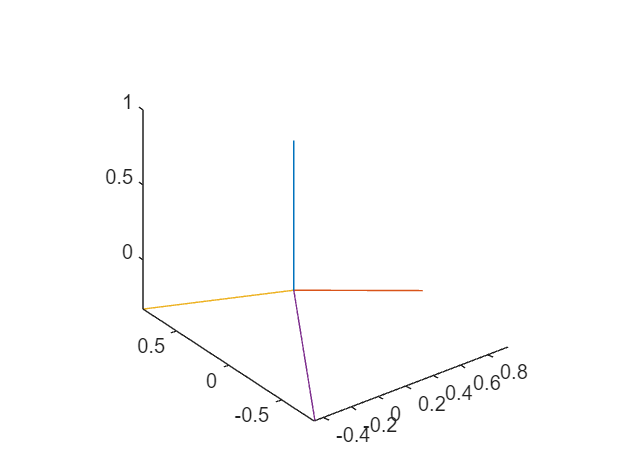


figure;
for j=1:4
    plot3([m4_rect_arr(j,2) 0],[m4_rect_arr(j,3) 0],[m4_rect_arr(j,4) 0]);
    hold on;
end
axis equal

% alpha_tb=[0,0,0];
% pre_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_tb,adj_list,mtype_all_arr)
% figure;
% moledraw(pre_xyz_tb,adj_list)
% 
% [pre_sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(pre_xyz_tb,nhc_all_tb,bs_tb,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb,big_adj_list,mtype_all_arr)

% % 参数设置
% %maxmin_arr=table2array(max_xyz);
% alpha_min = 0;  % 请替换为实际的最小值
% alpha_max = 360; % 请替换为实际的最大值
% 
% % 将初始坐标矩阵转换为向量（fmincon需要向量输入）
% %x0 = pre_xyz_tb(:);  % 将n×3矩阵展平为3n×1向量
% 
% % 设置边界约束
% n = size(alpha_tb, 2);
% lb = alpha_min * ones(1,n);  % 下界向量
% ub = alpha_max * ones(1,n);  % 上界向量
% 
% % 增加随机性和多次重启策略
% num_runs = 1;  % 进行5次独立优化尝试，每次使用不同的初始值
% best_fval = Inf;
% best_a_opt = [];
% 
% swarm_count=100
% for run = 1:num_runs
%     % 每次运行时生成不同的初始粒子群
%     initial_swarm = alpha_min + (alpha_max - alpha_min) * rand(swarm_count, n);  % 随机生成初始粒子群
% 
%     % PSO参数设置
%     options = optimoptions('particleswarm', ...
%         'SwarmSize',swarm_count, ...               % 粒子群大小
%         'MaxIterations', 3, ...           % 最大迭代次数
%         'Display', 'iter', ...              % 显示优化过程
%         'FunctionTolerance', 1e-6, ...      % 设置较小的目标函数容差
%         'InitialSwarmMatrix', initial_swarm, ...  % 初始粒子群矩阵
%         'OutputFcn', @psoOutputFunction);   % 输出函数
% 
%     % 目标函数包装器
% 
%     objective_function = @(alpha_tb) objective_wrapper(alpha_tb,ac, nhc_all_tb,bs_tb,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb, adj_list,big_adj_list, mtype_all_arr);
% 
% 
%     % 执行粒子群优化
%     fprintf('开始第 %d 次优化...\n', run);
%     tic;
%     [opt_alpha_tb, fval] = particleswarm(objective_function, length(alpha_tb), lb, ub, options);
%     optimization_time = toc;
% 
%     % 如果当前结果更好，则更新最优解
%     if fval < best_fval
%         best_fval = fval;
%         best_a_opt = opt_alpha_tb;
%     end
% 
%     % 显示每次优化的时间和目标函数值
%     fprintf('第 %d 次优化完成！\n', run);
%     fprintf('优化时间: %.2f 秒\n', optimization_time);
%     fprintf('当前目标函数值: %f\n', fval);
% end
% 
% % 显示最终优化结果
% fprintf('全局最优解已找到！\n');
% fprintf('优化完成，最优目标函数值: %f\n', best_fval);
% fprintf('最终优化时间: %.2f 秒\n', optimization_time);
% 
% 
% % 目标函数包装器
% function sumE = objective_wrapper(alpha_tb,ac, nhc_all_tb,bs_tb,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb, adj_list,big_adj_list, mtype_all_arr)
% 
% mid_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_tb,adj_list,mtype_all_arr);
% [sumE,~,~,~,~,~,~]=getE(mid_xyz_tb,nhc_all_tb,bs_tb,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb,big_adj_list,mtype_all_arr);
% 
% end
% % 自定义输出函数
% function stop = psoOutputFunction(~, optimValues, ~)
%     stop = false;
%     % 检查 optimValues 中的字段名，避免错误访问
%     if isfield(optimValues, 'Generation') && isfield(optimValues, 'BestFitness')
%         % 每20次迭代输出一次中间结果
%         if mod(optimValues.Generation, 20) == 0
%             fprintf('迭代次数: %d, 当前目标函数值: %.4f\n', ...
%                 optimValues.Generation, optimValues.BestFitness);
%         end
%     else
%         % 输出其他可用信息（如果字段名有所不同）
%         disp('当前optimValues中没有Generation或BestFitness字段');
%     end
% end


% opt_xyz_tb=xyzprecal(best_a_opt,ac,nh_tb,adj_list,mtype_all_arr);

% record_tb=zeros(90,2)
% min_jk=[0,0]
% min_E=100
% opt_xyz_tb=[];
% 
% for j=50
%     for k=1:1:180
%         alpha_tb=[10,j,k];
%         pre_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_tb,adj_list,mtype_all_arr);
%         [sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(pre_xyz_tb,nhc_all_tb,bs_tb,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb,big_adj_list,mtype_all_arr);
% 
%         if min_E>sumE
%             min_jk=[j,k];
%             min_E=sumE;
%             opt_xyz_tb=pre_xyz_tb;
%         end
%         record_tb(k,:)=[k,sumE];
%         if mod(k,20)==0
%             disp(k)
%         end
%     end
% 
% end

% % figure;
% % plot(record_tb(:,1),record_tb(:,2),"-")
% 
% figure;
% subplot(1,2,1)
% moledraw(pre_xyz_tb,adj_list)
% title("优化前")
% 
% subplot(1,2,2)
% moledraw(opt_xyz_tb,adj_list)
% title("优化后")
% pre_sumE
% 
% % min_E
% % min_jk

% pre_xyz_tb
% opt_xyz_tb



function tb=readcsv(csv_filename)
csv_folder = "../Values/MMFF94_CSV";
tb = readtable(fullfile(csv_folder,csv_filename));
end

function rect=sphe2rect(r,theta,varphi)
x=r*sind(varphi)*cosd(theta);
y=r*sind(varphi)*sind(theta);
z=r*cosd(varphi);
rect=[x,y,z];
end

function r0=r0find(r0_tb,mtype_tb,seq_i,seq_j)
mtype_i=mtype_tb(seq_i+1,1);
mtype_j=mtype_tb(seq_j+1,1);
row=matchmtype("R0",r0_tb,[mtype_i,mtype_j],["MTYPE_I","MTYPE_J"],"No");
r0=row{1,"R0"};
end


function [vec_ox,vec_oy,vec_oz]=gencoosys(xyz_tb,now_parent,now_child)
% 求解oz
vec_oz=xyz_tb(now_child+1,:)-xyz_tb(now_parent+1,:);
vec_oz=vec_oz/norm(vec_oz);

%求解ox
%vec_ox=genvec_xyz(zeros(1,3));
vec_ox=zeros(1,3);
vec_ox(1,1)=1;
vec_ox(1,2)=0;
c_xz=dot(vec_ox,vec_oz);
if c_xz~=0
    vec_ox(1,3)=c_xz/vec_oz(1,3);
end
vec_ox=vec_ox/norm(vec_ox);
%% 求解oy
vec_oy=cross(vec_oz,vec_ox);
vec_oy=vec_oy/norm(vec_oy);
end

% function B=genbase(ox,oy,oz)
% B=[table2array(ox)' table2array(oy)' table2array(oz)';];
% end
function p=line_parent_child(xyz_tb,parent,child)
p=plot3([xyz_tb(child,1),xyz_tb(parent,1)], ...
    [xyz_tb(child,2),xyz_tb(parent,2)], ...
    [xyz_tb(child,3),xyz_tb(parent,3)],"-",LineWidth=1.5);
end

% function EB=getEB(r_ij,bs_tb,mtype_arr)
% row=matchmtype(["R0","KB"],bs_tb,mtype_arr,["MTYPE_I","MTYPE_J"],"No");
% kb=row{1,"KB"};
% r0=row{1,"R0"};
% delta_r=r_ij-r0;
% cs=-2;
% EB=143.9525*kb/2*delta_r^2*(1+cs*delta_r+7/12*cs^2*delta_r^2);
% end

function EB=newgetEB(dr_ij,kb)
cs=-2;
dr_ij=r_ij-r0;
EB=143.9525*kb/2*dr_ij^2*(1+cs*dr_ij+7/12*cs^2*dr_ij^2);
end

% function EA=getEA(var_ij,ab_tb,mtype_arr)
% row=matchmtype(["THETA_0","KA_IJK"],ab_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
% ka=row{1,"KA_IJK"};
% var0=row{1,"THETA_0"};
% 
% cb=-0.000122;
% dvar=deg2rad(var_ij-var0);
% 
% EA=0.043844*ka/2*dvar^2*(1+cb*dvar);
% end

function EA=newgetEA(dvar,ka)
cb=-0.000122;
EA=0.043844*ka/2*dvar^2*(1+cb*dvar);
end

% function EBA=getEBA(var_ij,r_ij,r_kj,sb_tb,bs_tb,ab_tb,mtype_arr)
% row_ijk_1=matchmtype(["KBA_KJI","KBA_IJK"],sb_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
% kba_ijk=row_ijk_1{1,"KBA_IJK"};
% kba_kji=row_ijk_1{1,"KBA_KJI"};
% 
% row_ij=matchmtype("R0",bs_tb,mtype_arr(:,1:2),["MTYPE_I","MTYPE_J"],"No");
% r0_ij=row_ij{1,"R0"};
% 
% row_kj=matchmtype("R0",bs_tb,mtype_arr(:,2:3),["MTYPE_I","MTYPE_J"],"No");
% r0_kj=row_kj{1,"R0"};
% 
% row_ijk_2=matchmtype("THETA_0",ab_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K"],"No");
% var0=row_ijk_2{1,"THETA_0"};
% 
% dr_ij=r_ij-r0_ij;
% dr_kj=r_kj-r0_kj;
% dvar=deg2rad(var_ij-var0);
% 
% EBA=2.51210*(kba_ijk*dr_ij+kba_kji*dr_kj)*dvar;
% end

function EBA=getEBA(dr_ij,dr_kj,var_ijr)
EBA=2.51210*(kba_ijk*dr_ij+kba_kji*dr_kj)*dvar;
end

function EOOP=getEOOP(chi_ijkl,opb_tb,mtype_arr)
row=matchmtype("KOOP",opb_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K","MTYPE_L"],"Yes");
koop=row{1,"KOOP"};
EOOP=0.034844*koop/2*chi_ijkl^2;
end

function ET=getET(phi,ti_tb,mtype_arr)
row=matchmtype(["V1","V2","V3"],ti_tb,mtype_arr,["MTYPE_I","MTYPE_J","MTYPE_K","MTYPE_L"],"No");
V1=row{1,"V1"};
V2=row{1,"V2"};
V3=row{1,"V3"};
ET=0.5*(V1*(1+cosd(phi))+V2*(1-cosd(2*phi)+V3*(1+cosd(3*phi))));
end

function [Rv_ij,epsilon_ij]=precalEVDWParam(vdw_tb,mtype_arr)
mi=mtype_arr(1,1);
mj=mtype_arr(1,2);
A_i=vdw_tb{mi,"A_I"};
A_j=vdw_tb{mj,"A_I"};
G_i=vdw_tb{mi,"G_I"};
G_j=vdw_tb{mj,"G_I"};
N_i=vdw_tb{mi,"N_I"};
N_j=vdw_tb{mj,"N_I"};
alpha_i=vdw_tb{mi,"ALPHA_I"};
alpha_j=vdw_tb{mj,"ALPHA_I"};

B=0.2;
beta=12;

Rv_ii=A_i*alpha_i^0.25;
Rv_jj=A_j*alpha_j^0.25;
gamma_ij=(Rv_ii-Rv_jj)/(Rv_ii+Rv_jj);
Rv_ij=0.5*(Rv_ii+Rv_jj)*(1+B*(1-exp(-beta*gamma_ij^2)));
epsilon_ij=181.16*G_i*G_j*alpha_i*alpha_j/((alpha_i/N_i)^0.5+(alpha_j/N_j)^0.5)/Rv_ij^6;
end

function EVDW=getEVDW(R_ij,Rv_ij,epsilon_ij)
%row_i=matchmtype(["N_I","A_I","G_I","ALPHA_I"],vdw_tb,[mtype_arr(1,1)],"MTYPE","No");
%row_j=matchmtype(["N_I","A_I","G_I","ALPHA_I"],vdw_tb,[mtype_arr(1,2)],"MTYPE","No");


EVDW=epsilon_ij*(1.07*Rv_ij/(R_ij+0.07*Rv_ij))^7*(1.12*Rv_ij^7/(R_ij+0.12*Rv_ij^7)-2);
end

function row=matchmtype(des_ch,tb,mtype_arr,mtype_ch,is_jl_solid)
dsize=size(des_ch,2);
row=array2table(zeros(1,dsize),"VariableNames",des_ch);

for i=1:size(tb,1)
    rm=tb{i,mtype_ch};
    judge=false;
    if is_jl_solid~="Yes"
        rm_f=fliplr(rm);
        judge=isequal(rm,mtype_arr) || isequal(rm_f,mtype_arr);
    else
        if mtype_arr(1,2)==rm(1,2)&& mtype_arr(1,4)==rm(1,4)
            judge=mtype_arr(1,1)==rm(1,1)||mtype_arr(1,3)==rm(1,3);
        end
    end
    if judge
        for j=1:size(des_ch,2)
            row{1,des_ch(1,j)}=tb{i,des_ch(1,j)};
        end
        break
    end
end
end


function m_rect_arr=arr_sphe2rect(m_sphe_arr)
m_rect_arr=zeros(size(m_sphe_arr));
for i=1:size(m_sphe_arr,1)
    rect=sphe2rect(m_sphe_arr(i,2),m_sphe_arr(i,3),m_sphe_arr(i,4));
    m_rect_arr(i,:)=[m_sphe_arr(i,1),rect];
end
% m4_name=["Seq","X","Y","Z"];
% m_rect_tb=array2table(m4_rect,"VariableNames",m4_name);
end

function r=xyz2r(xyz_ij)
r=sqrt(sum((xyz_ij(1,:)-xyz_ij(2,:)).^2));
end

function vartheta=xyz2vartheta(xyz_ijk)
a=xyz_ijk(1,:)-xyz_ijk(2,:);
b=xyz_ijk(3,:)-xyz_ijk(2,:);
vartheta=acosd(dot(a,b)/(norm(a)*norm(b)));
end

function phi=xyz2phi(xyz_ijkl)
a=xyz_ijkl(1,:)-xyz_ijkl(2,:);
b=xyz_ijkl(3,:)-xyz_ijkl(2,:);
c=xyz_ijkl(4,:)-xyz_ijkl(3,:);

n_ab=cross(a,b);
n_bc=cross(b,c);

phi_1=acosd(dot(n_ab,n_bc)/norm(n_ab)/norm(n_bc));
k=-dot(a,b)/dot(b,b);
d=a+k*b;
judge=dot(d,c)<0;
if judge
    phi=180-phi_1;
else
    phi=phi_1;
end
end

function chi=xyz2chi(xyz_ijkl)
a=xyz_ijkl(1,:)-xyz_ijkl(2,:);
b=xyz_ijkl(3,:)-xyz_ijkl(2,:);
c=xyz_ijkl(4,:)-xyz_ijkl(2,:);
n=cross(a,b);
chi=abs(90-acosd(dot(c,n)/norm(c)/norm(n)));
end

function rec_node=bfs_finddepth(adj_list,start_pos,depth)
adj_key={num2str(start_pos)};
if depth==0 || ~isKey(adj_list,adj_key)
    rec_node= start_pos;
    return
else
    now_node_arr=adj_list(adj_key);
    now_node_arr=now_node_arr{:};
    rec_node=start_pos;
    for i=1:size(now_node_arr,2)
        rec_node=[rec_node, bfs_finddepth(adj_list,now_node_arr(1,i),depth-1)];
    end
end
end

%% 初始三维坐标生成
function xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_tb,adj_list,mtype_all_arr)

%% 待修改部分
m4_sphe_arr=table2array(readtable("M4.csv"));

nhc=size(nhc_all_tb,1);
xyz_tb=zeros(ac,3);

rec_xyz=[1 zeros(1,ac-1)];

for j=1:nhc
    now_parent=j-1;
    m=nhc_all_tb(j,1);
    if m~=4
        disp(m)
        continue
    end
    nb_node=adj_list({num2str(now_parent)});
    nb_node=nb_node{:};
    nsize=size(nb_node,2);

    new_m4_arr=m4_sphe_arr;
    new_m4_arr(:,3)=mod(m4_sphe_arr(:,3)+alpha_tb(1,j),360);
    m4_rect_arr=arr_sphe2rect(new_m4_arr);
    for i=1:nsize
        now_child=nb_node(1,i);
        r0=r0find(bs_tb,mtype_all_arr,now_parent,now_child);
        if i==1
            %% 第二个原子
            if j==1
                xyz_tb(now_child+1,:)=[0,0,r0];
                rec_xyz(1,now_child+1)=1;
            end
            %% 确定坐标系II基矢ox,oy,oz
            [vec_ox,vec_oy,vec_oz]=gencoosys(xyz_tb,now_parent,now_child);

            B=[vec_ox; vec_oy; vec_oz];

        elseif now_child>now_parent &&rec_xyz(1,now_child+1)==0
            %% 向量旋转公式
            adot=m4_rect_arr(i,2:end)*B;
            xyz_i=(r0*adot/norm(adot))+xyz_tb(now_parent+1,:);
            xyz_tb(now_child+1,:)=xyz_i;
            rec_xyz(1,now_child+1)=1;
        end
    end

end

end

function moledraw(xyz_tb,adj_list)
nhc=size(keys(adj_list),1);
for j=1:nhc
    nb_node=adj_list({num2str(j-1)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    for i=1:nsize
        line_parent_child(xyz_tb,j,nb_node(1,i)+1);
        hold on;
    end
end
for i=1:size(xyz_tb,1)
    text(xyz_tb(i,1),xyz_tb(i,2),xyz_tb(i,3),num2str(i));
end
axis equal
grid on
box off
xlabel("X")
ylabel("Y")
zlabel("Z")

end


function [sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(xyz_tb,nh_all_tb,bs_pro_arr,ab_tb,sb_tb,opb_tb,ti_tb,vdw_tb,big_adj_list,mtype_all_arr)

%% 总势能计算
sumEB=0;
sumEA=0;
sumEBA=0;
sumEOOP=0;
sumET=0;
sumEVDW=0;

ac=size(xyz_tb,1);
nhc=size(nh_all_tb,1);

max_m=6;
r_ij_tb=zeros(ac,ac);
var_ijk_tb=zeros(nhc,max_m,max_m);

mtype_short = sort(unique(mtype_all_arr, 'rows', 'stable'),1);
max_mtype_count=size(mtype_short,1);
max_mtype=max(mtype_short,[],"all");
mtype_2_mid=zeros(max_mtype,1);
for i=1:max_mtype_count
    mt=mtype_short(i,1);
    mtype_2_mid(mt,1)=i;
end

Rv_ij_mid_tb=zeros(max_mtype_count,max_mtype_count);
epsilon_ij_mid_tb=zeros(max_mtype_count,max_mtype_count);

Rv_ij_tb=zeros(ac,ac);
epsilon_ij_tb=zeros(ac,ac);

for i=1:max_mtype_count
    for j=1:max_mtype_count
        [Rv_ij_mid_tb(i,j),epsilon_ij_mid_tb(i,j)]=precalEVDWParam(vdw_tb,mtype_all_arr(mtype_short([i,j],1),1)');
        Rv_ij_mid_tb(j,i)=Rv_ij_mid_tb(i,j);
        epsilon_ij_mid_tb(j,i)=epsilon_ij_mid_tb(i,j);
    end
end

for j=1:nhc
    now_parent_j=j-1;
    nb_node=big_adj_list({num2str(now_parent_j)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    for i=1:nsize
        for k=(i+1):nsize
            now_child_i=nb_node(1,i);
            now_child_k=nb_node(1,k);
            index_ijk=[now_child_i,now_parent_j,now_child_k]+1;

            xyz_ijk=xyz_tb(index_ijk,:);
            var_ijk_tb(j,i,k)=xyz2vartheta(xyz_ijk);

        end
    end
end
for j=1:ac
    for i=j:ac
        if (i~=j)
            xyz_ij=xyz_tb([i j],:);
            r_ij_tb(i,j)=xyz2r(xyz_ij);
            r_ij_tb(j,i)=r_ij_tb(i,j);
        end

        index_ij=[i,j];
        mtype_ij=mtype_all_arr(index_ij,1)';
        new_id=mtype_2_mid(mtype_ij,1)';
        Rv_ij_tb(i,j)=Rv_ij_mid_tb(new_id(1,1),new_id(1,2));
        Rv_ij_tb(j,i)=Rv_ij_tb(i,j);
        epsilon_ij_tb(i,j)=epsilon_ij_mid_tb(new_id(1,1),new_id(1,2));
        epsilon_ij_tb(j,i)=epsilon_ij_tb(i,j);
    end
end
%% 计算各个能量
for j=1:nhc
    now_parent_j=j-1;
    nb_node=big_adj_list({num2str(now_parent_j)});
    nb_node=nb_node{:};
    nsize=size(nb_node,2);

    %% EB：对第i个原子只遍历编号比i大的相邻节点
    for i=1:nsize
        now_child=nb_node(1,i);
        if now_child>now_parent_j
            index_ij=[now_child,now_parent_j]+1;
            r_ij=r_ij_tb(index_ij(1,1),index_ij(1,2));
            mtype_ij=mtype_all_arr(index_ij,1)';
            sumEB=sumEB+getEB(r_ij,bs_pro_arr,mtype_ij);
        end
    end

    %% EA：遍历中心原子
    %% EBA：同EA
    for i=1:nsize
        for k=(i+1):nsize
            now_child_i=nb_node(1,i);
            now_child_k=nb_node(1,k);

            index_ijk=[now_child_i,now_parent_j,now_child_k]+1;
            mtype_ijk=mtype_all_arr(index_ijk,1)';

            var_ij=var_ijk_tb(j,i,k);
            r_ij=r_ij_tb(index_ijk(1,1),index_ijk(1,2));
            r_kj=r_ij_tb(index_ijk(1,2),index_ijk(1,3));

            sumEA=sumEA+getEA(var_ij,ab_tb,mtype_ijk);
            sumEBA=sumEBA+getEBA(var_ij,r_ij,r_kj,sb_tb,bs_pro_arr,ab_tb,mtype_ijk);

        end
    end
    %% EOOP：仅AllBond=3时
    if nsize==3
        for l=1:nsize
            now_child_l=nb_node(1,l);
            now_node_arr=nb_node;
            now_node_arr(1,l)=[];
            now_child_i=now_node_arr(1,1);
            now_child_k=now_node_arr(1,2);

            index_ijkl=[now_child_i,now_parent_j,now_child_k,now_child_l]+1;
            xyz_ijkl=xyz_tb(index_ijkl,:);
            chi_ijkl=xyz2chi(xyz_ijkl);
            mtype_ijkl=mtype_all_arr(index_ijkl,1)';
            sumEOOP=sumEOOP+getEOOP(chi_ijkl,opb_tb,mtype_ijkl);
        end
    end

    %% ET：同EB
    for k =j:nsize
        now_parent_k=nb_node(1,k);
        if now_parent_k<nhc
            node_i_arr=sort(cell2mat(big_adj_list({num2str(now_parent_j)})));
            node_l_arr=sort(cell2mat(big_adj_list({num2str(now_parent_k)})));
            insize=size(node_i_arr,2);
            lnsize=size(node_l_arr,2);
            for i=1:insize
                for l=1:lnsize
                    now_child_i=node_i_arr(1,i);
                    now_child_l=node_l_arr(1,l);
                    if now_child_l~=now_parent_j&&now_parent_k~=now_child_i
                        index_ijkl=[now_child_i,now_parent_j,now_parent_k,now_child_l]+1;
                        xyz_ijkl=xyz_tb(index_ijkl,:);
                        mtype_ijkl=mtype_all_arr(index_ijkl,1)';
                        phi=xyz2phi(xyz_ijkl);

                        sumET=sumET+getET(phi,ti_tb,mtype_ijkl);
                    end
                end
            end
        end
    end
end
for j=1:ac
    %% EVDW：BFS
    rec_node=bfs_finddepth(big_adj_list,j-1,2);
    rec_node_arr=zeros(1,ac);
    rnsize=size(rec_node,2);
    for ii=1:rnsize
        rec_node_arr(1,1+rec_node(1,ii))=true;
    end
    for bi=j:ac
        if rec_node_arr(1,bi)
            continue
        end
        index_ij=[j,bi];
        %mtype_ij=mtype_all_arr(index_ij,1)';
        R_ij=r_ij_tb(index_ij(1,1),index_ij(1,2));
        EVDW=getEVDW(R_ij,Rv_ij_tb(index_ij(1,1),index_ij(1,2)),epsilon_ij_tb(index_ij(1,1),index_ij(1,2)));
        sumEVDW=sumEVDW+EVDW;
    end
end
sumE=sumEB+sumEA+sumEBA+sumEOOP+sumET+sumEVDW;
end
